%Calculo de funcion de transferencias para el vantilador
%Importamos los datos obtenidos de las mediciones
opts = delimitedTextImportOptions("NumVariables", 2);
opts.DataLines = [2, Inf];
opts.Delimiter = ",";
opts.VariableNames = ["PWM", "TemperatureC"];
opts.VariableTypes = ["double", "double"];
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
data = readtable("D:\GD\Sistemas de control I\Trabajo-Integrador-SCI\Datos\pwm_temperature_data.csv", opts)

data = 100×2 table
     PWM      TemperatureC
    ______    ____________

         0       90.993   
    1.0101       89.117   
    2.0202       90.083   
    3.0303       91.228   
    4.0404       87.107   
    5.0505       86.501   
    6.0606       89.522   
    7.0707       87.292   
    8.0808       84.213   
    9.0909       85.631   
    10.101       83.013   
    11.111       82.402   
    12.121       83.211   
    13.131       78.295   
    14.141       78.065   
    15.152       79.785   


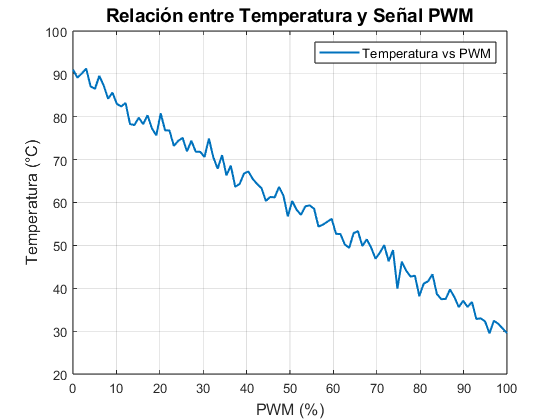


% Leer el archivo CSV como tabla
data = readtable("D:\GD\Sistemas de control I\Trabajo-Integrador-SCI\Datos\pwm_temperature_data.csv",opts);

% Separar las columnas en variables
PWM = data.("PWM"); % Columna PWM
Temperature = data.("TemperatureC"); % Columna Temperatura

% Crear el gráfico
figure;
plot(PWM, Temperature, 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Temperatura vs PWM');
grid on;
xlabel('PWM (%)', 'FontSize', 12);
ylabel('Temperatura (°C)', 'FontSize', 12);
title('Relación entre Temperatura y Señal PWM', 'FontSize', 14);
legend('show', 'Location', 'northeast', 'FontSize', 10);



% Crear entrada y salida como señales en tiempo (asumiendo un muestreo uniforme)
t = linspace(0, length(PWM)-1, length(PWM)); % Tiempo ficticio
u = PWM; %Entrada (PWM )
y = Temperature; % Salida (Temperatura)

% Ajustar un modelo de primer o segundo orden (dominio Laplace)
data_id = iddata(y, u, 1); % Crear datos de identificación con un muestreo ficticio de 1s
model = tfest(data_id, 1, 0); % Ajustar un modelo de primer orden sin ceros

% Mostrar la función de transferencia estimada
disp('Función de transferencia estimada:');

Función de transferencia estimada:


disp(model);

  idtf with properties:

        Numerator: -0.0038
      Denominator: [1 0.0070]
         Variable: 's'
          IODelay: 0
        Structure: [1×1 pmodel.tf]
    NoiseVariance: 3.3416
       InputDelay: 0
      OutputDelay: 0
               Ts: 0
         TimeUnit: 'seconds'
        InputName: {'u1'}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {'y1'}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
     SamplingGrid: [1×1 struct]
           Report: [1×1 idresults.tfest]



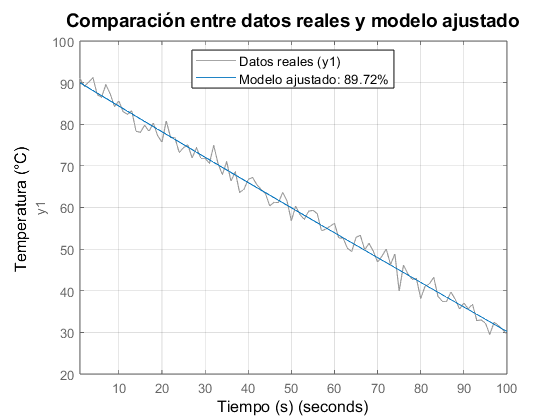


% Graficar comparación entre el modelo ajustado y los datos
figure;
compare(data_id, model);
title('Comparación entre datos reales y modelo ajustado', 'FontSize', 14);
xlabel('Tiempo (s)', 'FontSize', 12);
ylabel('Temperatura (°C)', 'FontSize', 12);
legend('Datos reales', 'Modelo ajustado', 'Location', 'best', 'FontSize', 10);
grid on;